                                 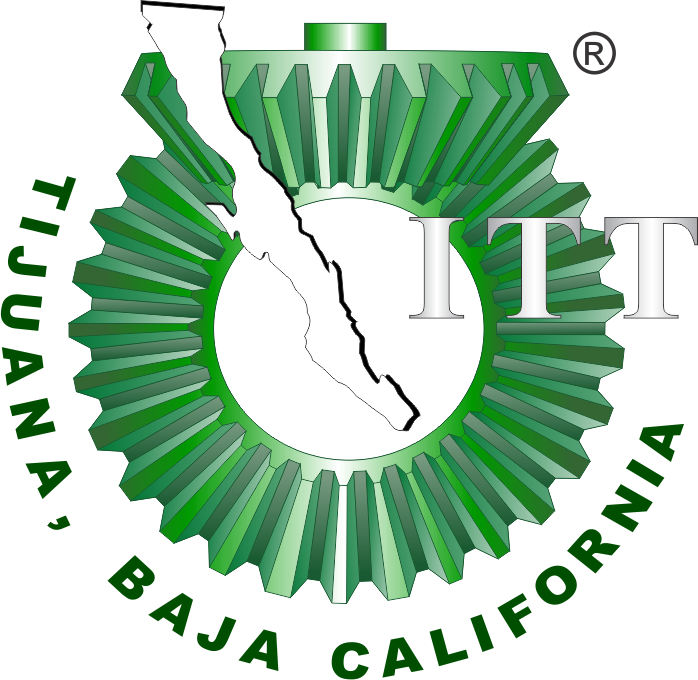

# Práctica 5.4: Sistema cardiovascular 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

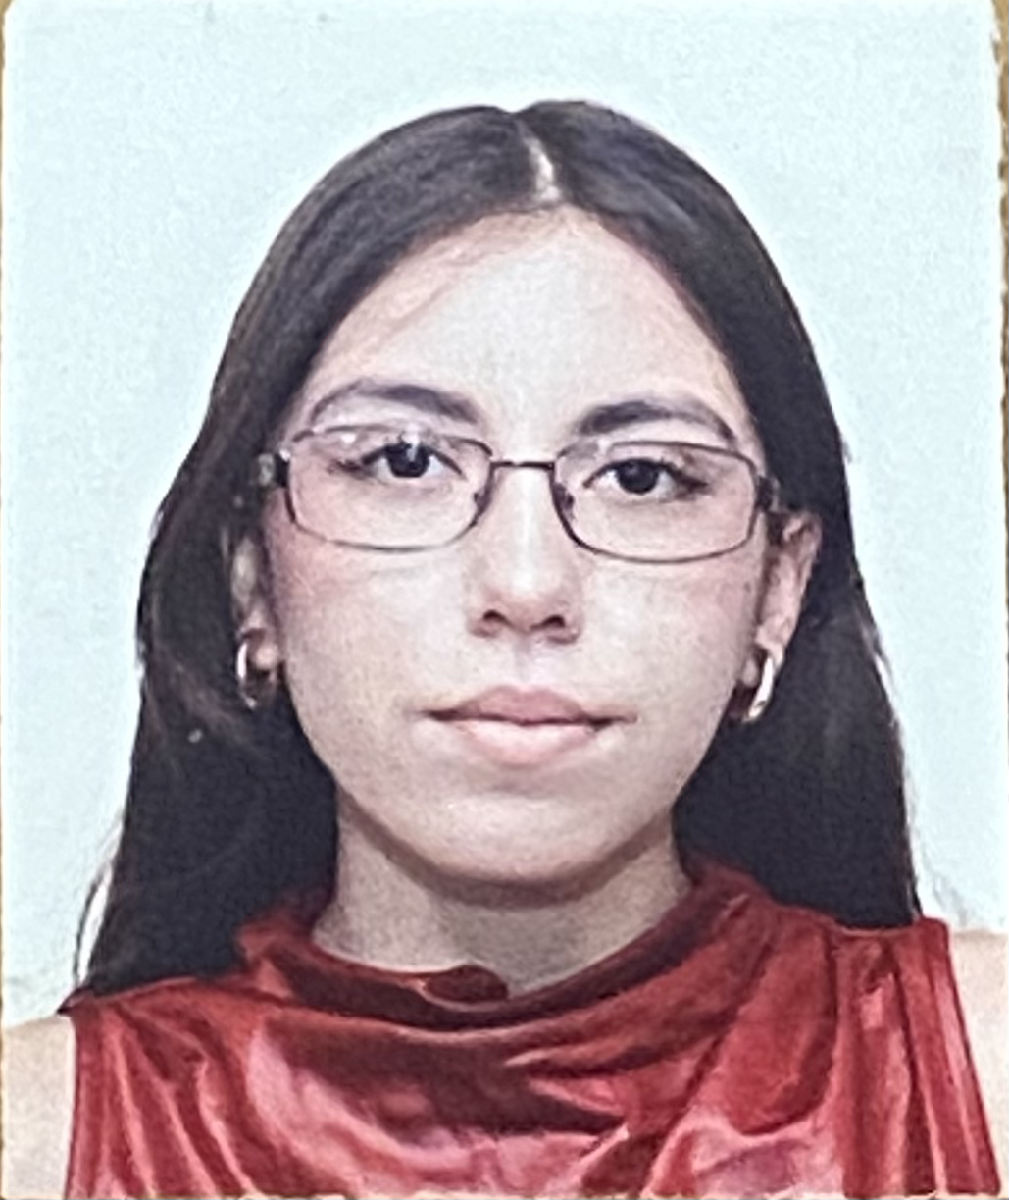

Nombre del alumno: Lopez Pardo Brianna Vanessa

Número de control: 22212261

Correo institucional: L22212261**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación 

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema';
open_system(file);
parameters.StopTime= tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
set_param ('Sistema/Ppa(t)', 'Minimum', '-0.2');
set_param ('Sistema/Ppa(t)', 'Maximum', '1');
set_param ('Sistema/Ppa(t)', 'Seed', '106');
set_param ('Sistema/Ppa(t)', 'SampleTime', '0.5 ');

## Lazo cerrado

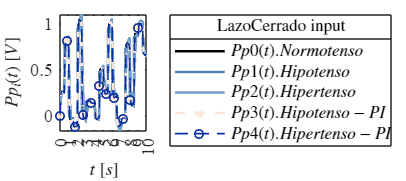

x = sim(file, parameters);
writematrix(x.Ppa, 'signal.xlsx')
plotsignals(x.t,x.Pp0,x.Pp1, x.Pp2, x.Pp3, x.Pp4)

## Lazo abierto

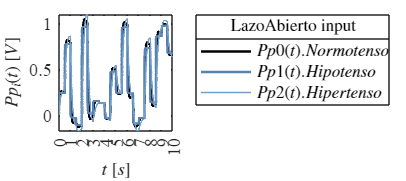

x = sim(file, parameters);
plotSignals(x.t,x.Pp0,x.Pp1, x.Pp2)

## Funcion: Respuesta en lazo cerrado

function plotsignals(t,Pp0,Pp1, Pp2, Pp3, Pp4)

Signal = 'LazoCerrado';


set(figure(),'Color','w')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman', 'FontSize', 11)
hold on; grid off; box on;

mycolors = [0,0,0;
    86,130,177;
    115,158,201;
    255,232,219;
    10,51,160;
    30,80,90]/255;
colororder(mycolors)
    
   p=   plot(t,Pp0,'-',t,Pp1,'-',t,Pp2,'-',t,Pp3,'--x', t,Pp4,'--o', ...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(5),'LineWidth',1);
    L = legend('$Pp0(t). Normotenso$','$Pp1(t). Hipotenso$','$Pp2(t). Hipertenso$','$Pp3(t). Hipotenso-PI$','$Pp4(t). Hipertenso-PI$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
     title(L,[Signal,' input'],'FontSize',10)

    xlabel('$t$ $[s]$', 'Interpreter', 'latex','FontSize', 11)
    ylabel('$Pp_i(t)$ $[V]$', 'Interpreter', 'latex','FontSize', 11)

    xlim([0,10]);xticks(0:1:10);

 
     exportgraphics(gcf,[Signal,'.pdf'],'ContentType', 'vector');
     exportgraphics(gcf,[Signal,'.png'],'ContentType', 'vector');
end



## Funcion: Respuesta en lazo abierto

function plotSignals(t,Pp0,Pp1, Pp2)

Signal = 'LazoAbierto';

set(figure(),'Color','w')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman', 'FontSize', 11)
hold on; grid off; box on;

mycolors = [0,0,0;
    86,130,177;
    115,158,201;
    255,232,219;
    10,51,160;
    30,80,90]/255;
colororder(mycolors)
    
   p=   plot(t,Pp0,'-',t,Pp1,'-',t,Pp2,'-', ...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3),'LineWidth',1);
    L = legend('$Pp0(t). Normotenso$','$Pp1(t). Hipotenso$','$Pp2(t). Hipertenso$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
     title(L,[Signal,' input'],'FontSize',10)

    xlabel('$t$ $[s]$', 'Interpreter', 'latex','FontSize', 11)
    ylabel('$Pp_i(t)$ $[V]$', 'Interpreter', 'latex','FontSize', 11)

    xlim([0,10]);xticks(0:1:10);

     exportgraphics(gcf,[Signal,'.pdf'],'ContentType', 'vector');
     exportgraphics(gcf,[Signal,'.png'],'ContentType', 'vector');
end